Math 155 Final Project

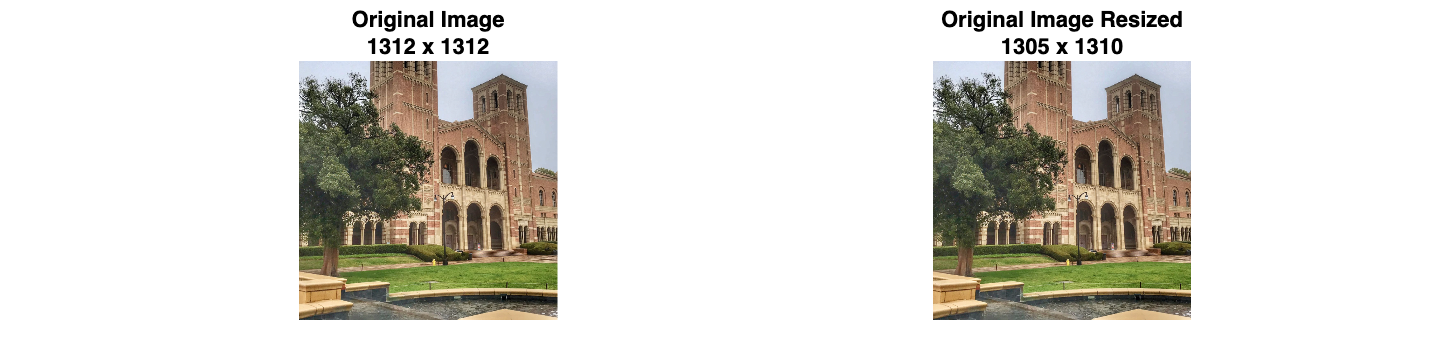

clear;clc;close all;

% import image we want to make a mosaic of
img = imread("royce2.png");

% get size of original image
[img_y, img_x] = size(img,1,2);

% plot original image
figure
set(gcf, 'Position', [100,100,800,200])
subplot(1,2,1)
imshow(img)
title({'Original Image'; string(img_x) + ' x ' + string(img_y)})

% set desired tile size
tile_x = 15;
tile_y = 10;

% import subset of image tiles that will make up the mosaic
listing = dir(['Random' '/*.' 'jpeg']);

% find number of unique image tiles
n = size(listing, 1); 

% store image tiles in cell array called tiles
% ensure that all tiles are the same dimensions
for i = 1:n
    imageName = listing(i).name;
    tiles{i} = imread(['Random' '/' imageName],'jpeg');
    tiles{i} = imresize(tiles{i},[tile_y tile_x]);
end

% compute number of tiles across and down in  mosaic
% this is based off of the original image size and tile size
num_tiles_across = floor( img_x / tile_x );
num_tiles_down = floor( img_y / tile_y );

% resize original image to fit tiles
img_x = num_tiles_across * tile_x;
img_y = num_tiles_down * tile_y;
img = imresize(img,[img_y img_x]);

% plot resized original image
subplot(1,2,2)
imshow(img)
title({'Original Image Resized'; string(img_x) + ' x ' + string(img_y)})

% split image into tiles of original image 
% these orignal image tiles will be replaced with best fit image tiles later
img_tiles = cell(num_tiles_down, num_tiles_across); 

for i = 0 : num_tiles_down - 1
    for j = 0 : num_tiles_across - 1
        % x index
        x1 = j * tile_x + 1;
        x2 = (j+1) * tile_x;
        
        % y index
        y1 = i * tile_y + 1;
        y2 = (i+1) * tile_y;

        % store image tile
        img_tiles{i+1,j+1} = img( y1:y2, x1:x2, :);
    end
end

% compute average rgb intensity values for each tile in the orignal image
avg_img = zeros(num_tiles_down, num_tiles_across, 3);
for i = 1 : num_tiles_down
    for j = 1 : num_tiles_across
        current_tile = img_tiles{i,j};
        for rgb = 1:3
            avg_img(i,j,rgb) = mean(mean(current_tile(:,:,rgb)));
        end
    end
end

% compute average rgb intensity values for image tiles
avg_tiles = zeros(n,3);
for i = 1:n
    current_tile = tiles{i};
    for rgb = 1:3
        avg_tiles(i,rgb) = mean(mean(current_tile(:,:,rgb)));
    end
end

% find best fit image for each tile on grid
mosaic = cell(num_tiles_down, num_tiles_across);
for i = 1 : num_tiles_down
    for j = 1 : num_tiles_across
        min_dist = 100000;
        for k = 1:n
            dist = sqrt( ( avg_img(i,j,1) - avg_tiles(k,1))^2 + ( avg_img(i,j,2) - avg_tiles(k,2))^2 + ( avg_img(i,j,3) - avg_tiles(k,3))^2 );
            if dist < min_dist
                min_dist = dist;
                best_img = k;
            end
        end
        % save best image tile into cell array
        mosaic{i,j} = tiles{best_img};
    end
end

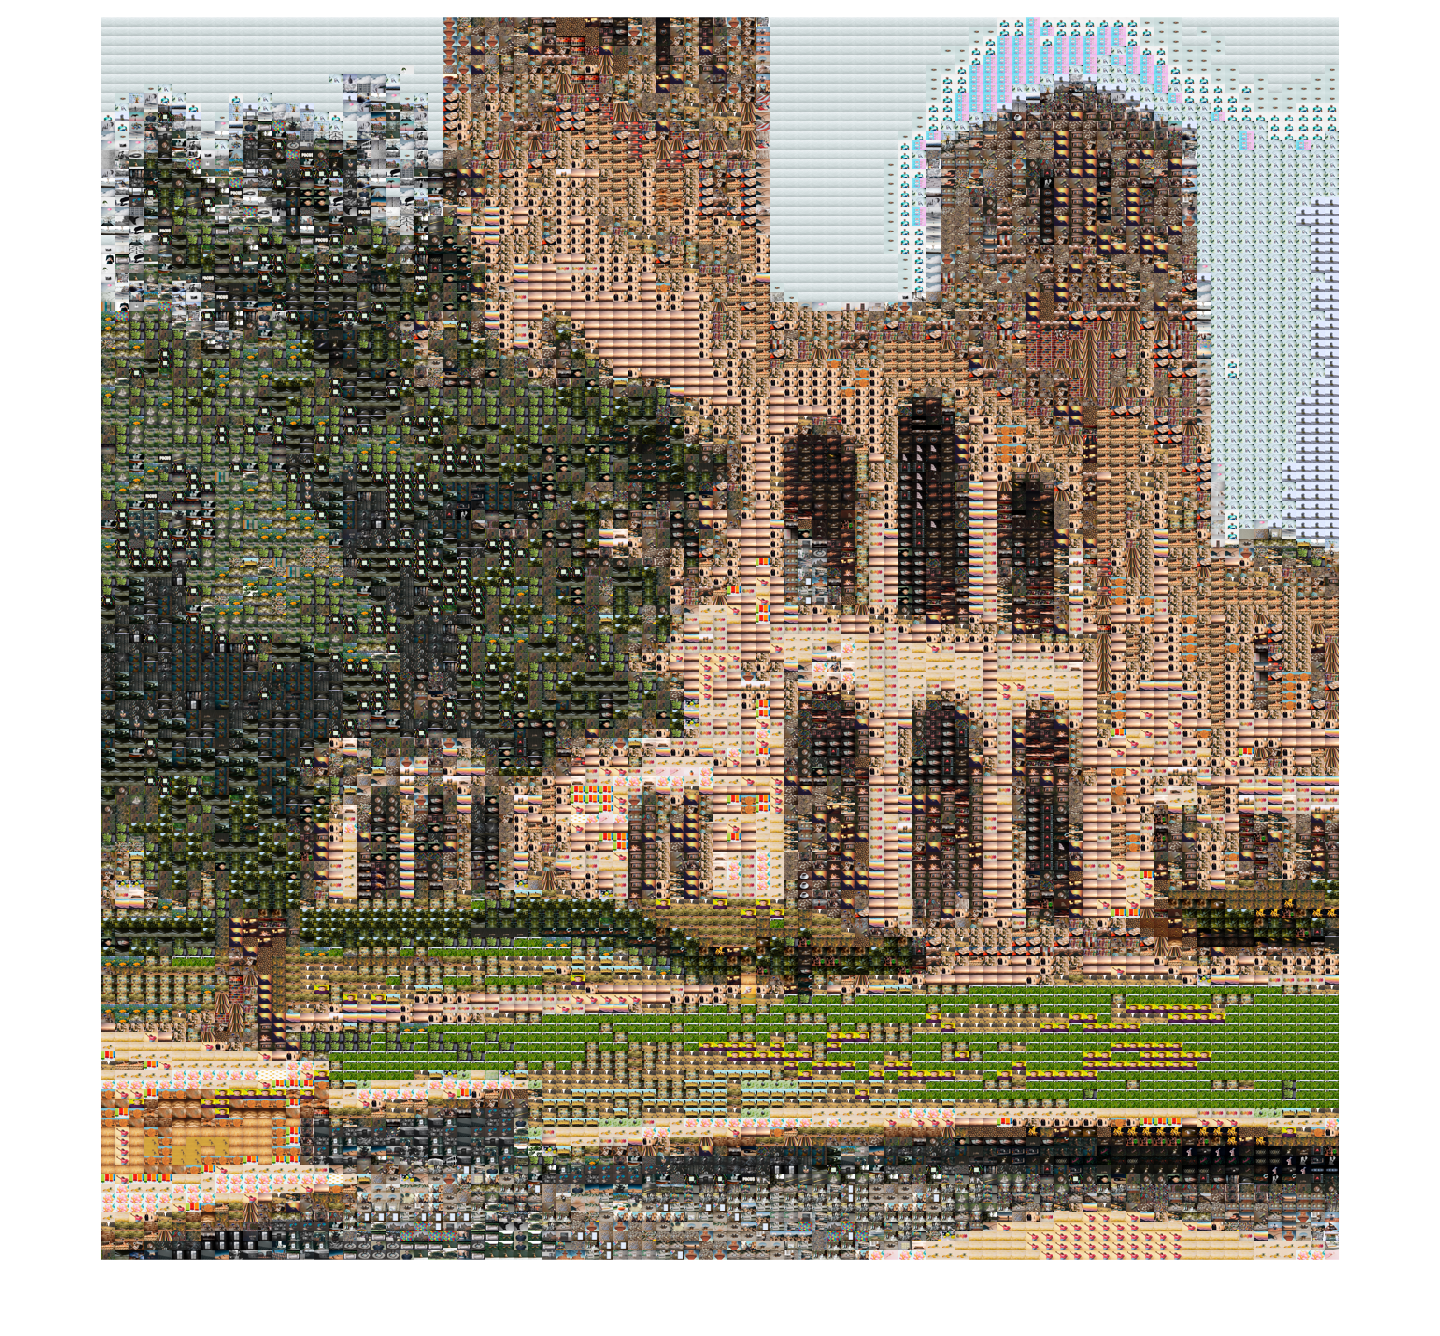

% construct mosaic
final_mosaic = cell2mat(mosaic);
figure
imshow(final_mosaic)